REAL TIME LOCK TEST:

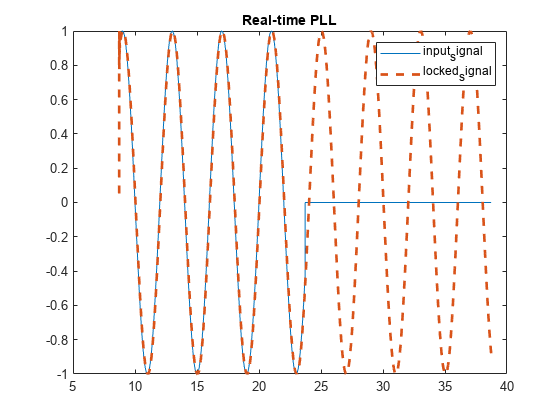

clear;
close all;
oscil_freq = 0.2;
lock_freq = 0.4;
lock_phase =  0*pi;
loop_gain = 0.41;
fs = 250;
counter = 0;
int1 = 10;
int2 = 10;
%figure;
t = 0;
x = t : 1/fs: t+15;
input_signal = sin(2 * pi * x *lock_freq + lock_phase);
            [y, phase] = DPLL(input_signal, 0, loop_gain, oscil_freq, fs);
            if lock_freq > oscil_freq
                y = cat(2, y, zeros(1, (length(input_signal)- length(y))));
            end
            if lock_freq < oscil_freq
                input_signal = cat(2, input_signal, zeros(1, (length(y) - length(input_signal))));
                x = t : 1/fs: t+length(input_signal)/fs-1/fs;
            end
            pause(0.04);
            t = t + 0.04;
while true 
        for i=0:int1/0.04
            oscil_freq = 0.5;
            lock_freq = 0.25;
            lock_phase =  0*pi;
            loop_gain = 0.5;
            clf;
            x = t : 1/fs: t+15;
            input_signal = sin(2 * pi * x *lock_freq + lock_phase);
            [y, phase] = DPLL(input_signal, phase, loop_gain, oscil_freq, fs);
            if lock_freq > oscil_freq
                y = cat(2, y, zeros(1, (length(input_signal)- length(y))));
            end
            if lock_freq < oscil_freq
                input_signal = cat(2, input_signal, zeros(1, (length(y) - length(input_signal))));
                x = t : 1/fs: t+length(input_signal)/fs-1/fs;
            end
            plot(x, input_signal, LineStyle="-")
            hold on;
            ylim([-1 1]);
            plot(x, y, LineStyle="--", LineWidth=2);
            title("Real-time PLL");
            legend("input_signal", "locked_signal");
            hold on;
            pause(0.04);
            t = t + 0.04;
        end
        for i=0:int2/0.04
            oscil_freq = 0.28;
            lock_freq = 0.6;
            lock_phase =  0.5*pi;
            loop_gain = 0.5;
            clf;
            x = t : 1/fs: t+15;
            input_signal = sin(2 * pi * x *lock_freq + lock_phase);
            [y, phase] = DPLL(input_signal, phase, loop_gain, oscil_freq, fs);
            if lock_freq > oscil_freq
                y = cat(2, y, zeros(1, (length(input_signal)- length(y))));
            end
            if lock_freq < oscil_freq
                input_signal = cat(2, input_signal, zeros(1, (length(y) - length(input_signal))));
                x = t : 1/fs: t+length(input_signal)/fs-1/fs;
            end
            plot(x, input_signal, LineStyle="-")
            hold on;
            ylim([-1 1]);
            plot(x, y, LineStyle="--", LineWidth=2);
            title("Real-time PLL");
            legend("input_signal", "locked_signal");
            hold on;
            pause(0.04);
            t = t + 0.04;
        end
        break
end

function [decimated] = decimate(inp, factor)
    if factor ~= 1
        [b,a] = butter(6, 1/factor, 'low');
        inp = filter(b, a, inp);
    end
decimated = zeros(1, ceil(length(inp)/factor));
    for i= 1: length(decimated)
        decimated(i) = inp(i*factor - factor +1);
    end
end

function [interpolated] = interpol(inp, factor)
if factor == 1
    interpolated = inp;
else

    interpolated = zeros(1, factor*length(inp));
        for i = 1: length(interpolated)
            if rem(i, factor) == 1
                interpolated(i) = inp(ceil(i/factor));
            end
        end

        [b,a] = butter(6, 1/factor, 'low');
        interpolated = factor * filter(b, a, interpolated);
        
end
end

function [rate_changed] = rate_change(inp, factor)
[up_factor, down_factor] = rat(factor);
upsampled = interpol(inp, up_factor);
rate_changed = decimate(upsampled, down_factor);
end

function [locked_signal, return_phase] = DPLL(inp, phase, loop_gain, oscil_freq, fs)
inp = inp / max(inp);
t = 0 : 1/fs : 15; % sampling freq is 100

freq = fft(inp, 100000);
[val, idx] = max(freq);
peak_freq = ((idx-1) * fs / 100000);
if peak_freq > fs/2
    peak_freq = fs - ((idx-1) * fs / 100000);
end

lag = phase * 2* pi + pi / 2;
oscil = sin(2*pi*oscil_freq*t + lag);

feedback_signal = rate_change(oscil, oscil_freq/peak_freq);

visualization_signal = sin(2*pi*oscil_freq*t + lag - pi/2);
locked_signal = rate_change(visualization_signal, oscil_freq/peak_freq);

feedback_signal = loop_gain * feedback_signal;
if length(feedback_signal)< length(inp)
    mixer = inp(1:length(feedback_signal)) .* feedback_signal;
else
    mixer = inp .* feedback_signal(1:length(inp));
end
% locked_signal = feedback_signal / loop_gain;
return_phase = phase + mean(mixer);
end


